**Random seed**

rng(01778525)

**Import Data**

train_data = readtable("train1778525.csv")

train_data = 500×6 table
    l100    mass    time100    displacement       type        colour  
    ____    ____    _______    ____________    __________    _________

    3.6      997      8.6          4.2         {'diesel'}    {'other'}
    4.8     2050     10.6          3.1         {'diesel'}    {'other'}
    4.6     1265      9.7          3.3         {'diesel'}    {'other'}
    4.3     1578      9.5          2.9         {'diesel'}    {'other'}
    4.9     2343     11.8          1.7         {'diesel'}    {'other'}
    3.7     1306      9.5          3.2         {'diesel'}    {'white'}
    5.1     1934     10.4          2.8         {'diesel'}    {'other'}
    3.9     2051     10.2          2.6         {'diesel'}    {'other'}
    2.6      960     12.6          1.6         {'diesel'}   

test_data = readtable("test1778525.csv")

test_data = 500×6 table
    l100    mass    time100    displacement       type        colour  
    ____    ____    _______    ____________    __________    _________

    3.4     2218     11.9            2         {'diesel'}    {'white'}
    3.8     1977     10.8          2.1         {'diesel'}    {'other'}
    4.6      983     10.8          2.1         {'diesel'}    {'other'}
      4     2310      9.9            2         {'diesel'}    {'white'}
    3.4     1233       12          1.9         {'diesel'}    {'other'}
    4.1     1004     10.1          3.1         {'diesel'}    {'other'}
    3.7      921     10.6          2.1         {'diesel'}    {'white'}
    3.7     1678      9.2          3.8         {'diesel'}    {'other'}
    3.1     1377     11.3          2.2         {'diesel'}    

**Store training data in arrays**

y = table2array(train_data(:,1));    % Fuel consumption
mass = table2array(train_data(:,2));
time = table2array(train_data(:,3)); % Acceleration time
disp = table2array(train_data(:,4)); % disp
fuel = table2array(train_data(:,5)); % Engine fuel type
color = table2array(train_data(:,6));

# **Question 1**

## **A) Summary statistics**

y_mean = mean(y)

y_mean = 4.9220

y_median = median(y)

y_median = 4.4000

y_std = std(y)

y_std = 1.5292

y_iqr = iqr(y)

y_iqr = 1.6000

Present in table

headers = ["Mean"; "Median"; "Standard deviation"; "Interquartile Range"];
y_stats = table(y_mean, y_median, y_std, y_iqr)

y_stats = 1×4 table
    y_mean    y_median    y_std     y_iqr
    ______    ________    ______    _____

    4.922       4.4       1.5292     1.6 


Plot histogram

y_hist = histogram(y,10)

y_hist =   Histogram with properties:

             Data: [500×1 double]
           Values: [22 139 166 61 38 26 27 13 7 1]
          NumBins: 10
         BinEdges: [2.4000 3.2400 4.0800 4.9200 5.7600 6.6000 7.4400 8.2800 9.1200 9.9600 10.8000]
         BinWidth: 0.8400
        BinLimits: [2.4000 10.8000]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


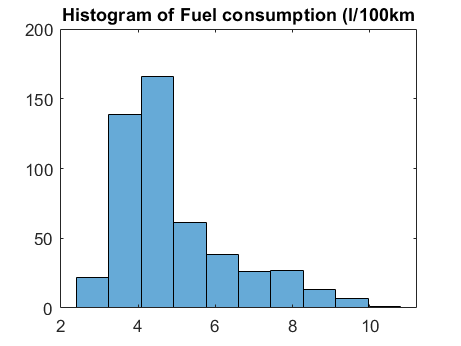

title("Histogram of Fuel consumption (l/100km")

The data is not symmetric so it makes more sense to use the median to describe the data rather than the mean

## **B) i ) Boxplots for categorical variables**

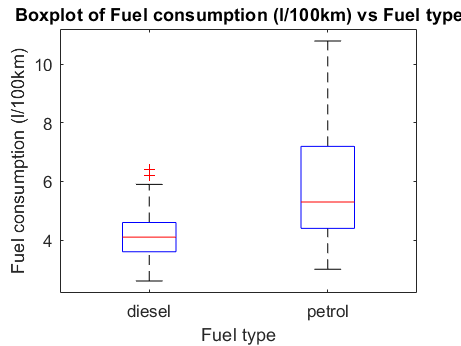

boxplot(y,fuel)
title("Boxplot of Fuel consumption (l/100km) vs Fuel type")
xlabel("Fuel type")
ylabel("Fuel consumption (l/100km)")

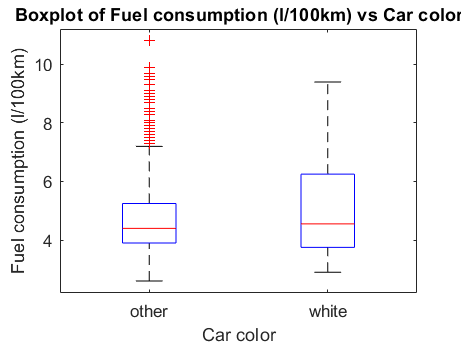


boxplot(y,color)
title("Boxplot of Fuel consumption (l/100km) vs Car color")
xlabel("Car color")
ylabel("Fuel consumption (l/100km)")

The first boxplot makes clear that fuel type matters greatly for fuel efficiency. Diesel Cars tend to consume less fuel than petrol cars. So they should be included in our model

The second boxplot for color shows similar median values, but the cars not colored white show great variability and many observations fall outside of the boxplot range. Intuitively we know that a cars color should not matter for fuel consumption. The skewed distribution of the non-white cars is most likely explained by other parameters.

Before proceeding I'll recode catergorial variables so diesel = 1, petrol = 2 

**Encode categorical variable fuel**


fuel = grp2idx(fuel) 

fuel =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


## **B)ii) Scatterplots of Continuous variables + correlation matrices**

**Mass**

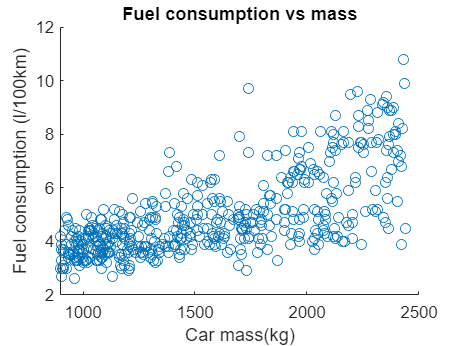

scatter(mass,y)
xlabel("Car mass(kg)")
ylabel("Fuel consumption (l/100km)")
title("Fuel consumption vs mass")

corrcoef(mass,y)

ans =     1.0000    0.6986
    0.6986    1.0000


There is evidently a relationship between fuel consumption and mass, as would be expected. The relationship appears to be roughly linear, so we can use it in our model without any transformations. And the correlation coyicient is fairly high.

**Acceleration time**

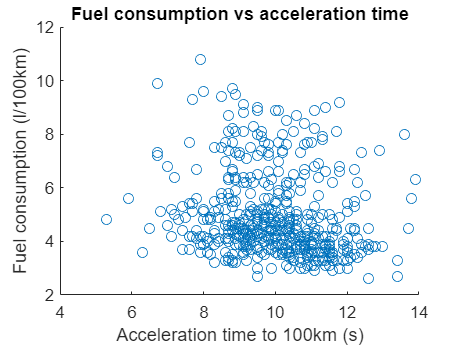

scatter(time,y)
xlabel("Acceleration time to 100km (s)")
ylabel("Fuel consumption (l/100km)")
title("Fuel consumption vs acceleration time")

corrcoef(time,y)

ans =     1.0000   -0.1780
   -0.1780    1.0000


We cant obviously see a linear relationship, so I will test some transformations

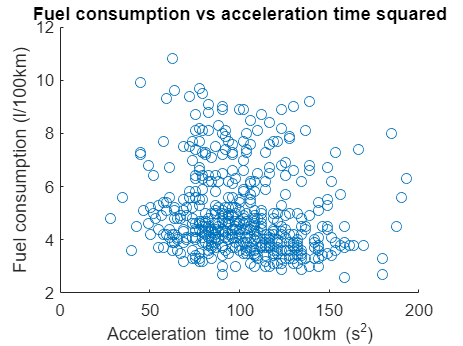

scatter(time.*time,y)
xlabel("Acceleration time to 100km (s^2)")
ylabel("Fuel consumption (l/100km)")
title("Fuel consumption vs acceleration time squared")

corrcoef(time.*time,y)

ans =     1.0000   -0.1752
   -0.1752    1.0000


This does not appear to give a good relationship either

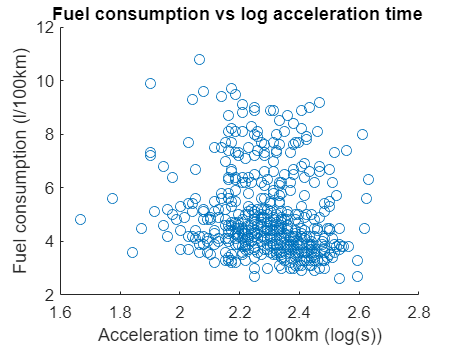

scatter(log(time),y)
xlabel("Acceleration time to 100km (log(s))")
ylabel("Fuel consumption (l/100km)")
title("Fuel consumption vs log acceleration time ")

corrcoef(log(time),y)

ans =     1.0000   -0.1777
   -0.1777    1.0000


Overall fuel consumption tends to have a slighlty negative correlation with acceleration time. Perhaps the acceleration time can be coupled with another variable, say engine disp, to create a stronger predictor.

Overall the time to reach 100km/h does not appear to be a very useful predictor, because cars with a given acceleration show widely carying fuel consumption patterns. But I will still test its effect on performance in my models.

**Engine displacement**

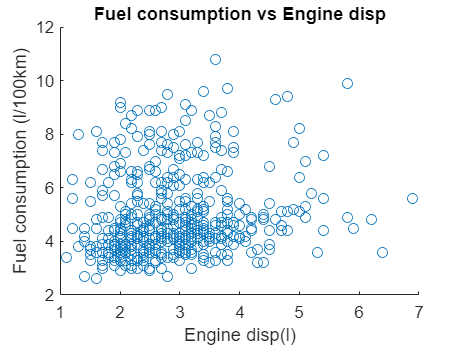

scatter(disp,y)
xlabel("Engine disp(l)")
ylabel("Fuel consumption (l/100km)")
title("Fuel consumption vs Engine disp")

corrcoef(disp,y)

ans =     1.0000    0.1640
    0.1640    1.0000


There seems to be a correlation with engine disp, even if the data is very dispersed. I will therefore make use of it with my model

# **Q2) Modelling Simple linear regression with just mass**

Start from simple models and work my way up by adding complexity

**Fit a linear regression for fuel consumption vs mass**

% Fit model and predict
model = fitlm(mass,y)

model = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate         SE        tStat       pValue  
                   _________    __________    ______    __________

    (Intercept)       1.3215       0.17237    7.6668    9.3149e-14
    x1             0.0023041    0.00010576    21.786    2.0893e-74


Number of observations: 500, Error degrees of freedom: 498
Root Mean Squared Error: 1.1
R-squared: 0.488,  Adjusted R-Squared: 0.487
F-statistic vs. constant model: 475, p-value = 2.09e-74

pred = model.predict(mass)

pred =     3.6188
    6.0450
    4.2363
    4.9575
    6.7201
    4.3307
    5.7777
    6.0473
    3.5335
    3.4736


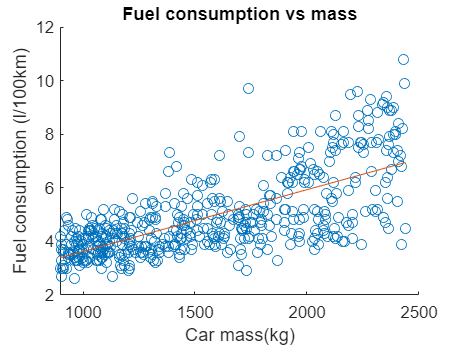

% Plot
scatter(mass,y)
hold on
plot(mass,pred)
xlabel("Car mass(kg)")
ylabel("Fuel consumption (l/100km)")
title("Fuel consumption vs mass")
hold off

Upon visual inspection the linear model with mass appears roughly in line with the data. However the model has an R2 value of only 0.48, meaning the change in mass can only explain 48% of the variability of the model, which means the linkage is weak. The root mean squared error of 1.1 is also quite significant, especially considering the interquartile range is 1.6.

In conclusion we need to make our model more complicated by adding more regression variables, while keeping mass in because it does explain some of the variablity.

# **B) Evaluate Performance Metrics**

**R^2 = 0.48**

rsquared = model.Rsquared

rsquared = struct with fields:
    Ordinary: 0.4880
    Adjusted: 0.4870


This gives us an indication of what % of the varibility in y can be explained by changes in x. As R <0.5 there appears to be a weak linkage with just mass itself

**MSE=1.1997**

mse = model.MSE

mse = 1.1997

This tells us the average of the squares of error,  by the predicions made by the regresison model. An MSE of roughly 1.2, and a RMSE of 1.1 suggests the model isn't performing very well, because our data for fuel yiciency is mostly in the single digits, with an iqr of 1.6 and mean and median of 4.92 and 4.4. A 1.1 RMSE error is quite signficiant given these summary statistics

**AIC=1512**

aic = model.ModelCriterion

aic = struct with fields:
     AIC: 1.5120e+03
    AICc: 1.5120e+03
     BIC: 1.5204e+03
    CAIC: 1.5224e+03


The Akaike information criterion is a mathematical method that evaluates how well a model fits the training data. AIC takes into account the number of independent varaibles used to build the model, and the maximum likelihood estimate of the model, so it allows us to pick the model taht explains the greatest amount of variation with the fewest independent varaible. Lower AIC scores are better

**Overall, **we should aim to maximise R2 and minimise MSE, but consider the change in aic as well when comparing models with similar R2 and MSE scores.

# **C) Test different models**

- **First plot some scatter plots of possible interaction terms I can use**

### Mass * fuel

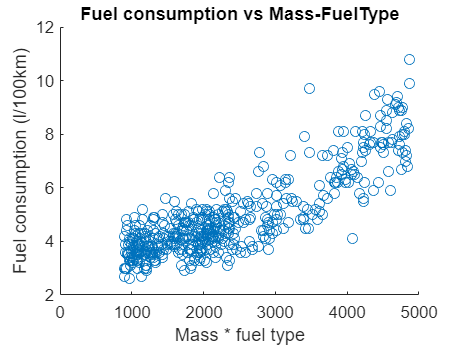

scatter(mass.*fuel,y)
xlabel("Mass * fuel type")
ylabel("Fuel consumption (l/100km)")
title("Fuel consumption vs Mass-FuelType")

corrcoef(mass.*fuel,y)

ans =     1.0000    0.8522
    0.8522    1.0000


This interaction term shows very strong correlation with fuel consumption

### disp * time

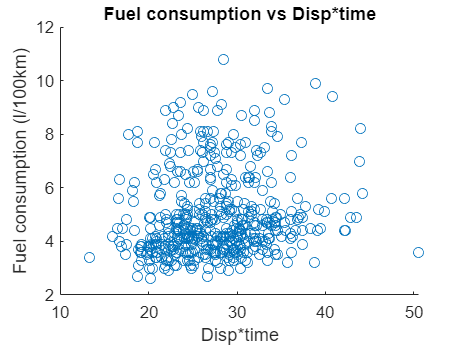

scatter(disp.*time,y)
xlabel("Disp*time")
ylabel("Fuel consumption (l/100km)")
title("Fuel consumption vs Disp*time")

corrcoef(disp.*time,y)

ans =     1.0000    0.1312
    0.1312    1.0000


Very weak correlation

### disp/time

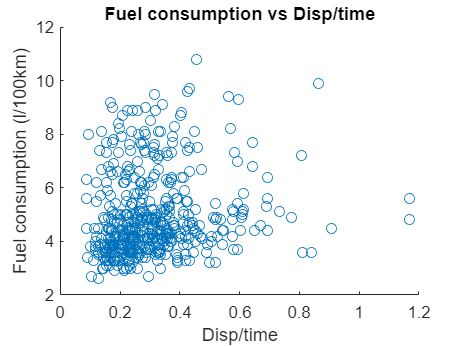

scatter(disp./time,y)
xlabel("Disp/time")
ylabel("Fuel consumption (l/100km)")
title("Fuel consumption vs Disp/time")

corrcoef(disp./time,y)

ans =     1.0000    0.1643
    0.1643    1.0000


This shows a slightly higher correlation than disp*time100 so I'll prefer this one over that.

### Mass*disp

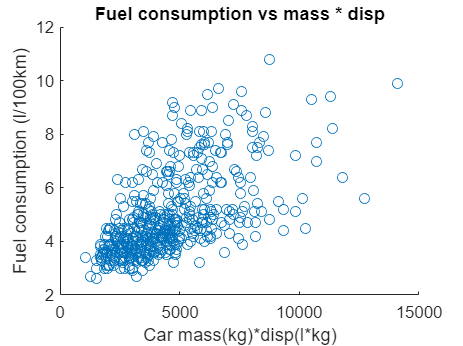

scatter(mass.*disp,y)
xlabel("Car mass(kg)*disp(l*kg)")
ylabel("Fuel consumption (l/100km)")
title("Fuel consumption vs mass * disp")

corrcoef(mass.*disp,y)

ans =     1.0000    0.5863
    0.5863    1.0000


A visible correlation, though we'll see if it adds any useful info if we already have mass and disp in the model

### Fuel*disp

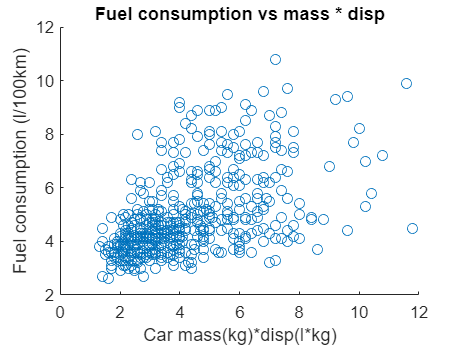

scatter(fuel.*disp,y)
xlabel("Car mass(kg)*disp(l*kg)")
ylabel("Fuel consumption (l/100km)")
title("Fuel consumption vs mass * disp")

corrcoef(mass.*disp,y)

ans =     1.0000    0.5863
    0.5863    1.0000


I could go on to try countless other combinations and parametric forms but the above seem good enough to work with.

# Create table to populate with summary stats for the models I wish to test

sz = [10 5];
varTypes = ["double","string", "double","double","double"];
varNames = ["Model#", "Terms", "R^2", "MSE", "AIC"];
model_summaries = table('Size',sz,'VariableTypes',varTypes,'VariableNames',varNames)

model_summaries = 10×5 table
    Model#      Terms      R^2    MSE    AIC
    ______    _________    ___    ___    ___

      0       <missing>     0      0      0 
      0       <missing>     0      0      0 
      0       <missing>     0      0      0 
      0       <missing>     0      0      0 
      0       <missing>     0      0      0 
      0       <missing>     0      0      0 
      0       <missing>     0      0      0 
      0       <missing>     0      0      0 
      0       <missing>     0      0      0 
      0       <missing>     0      0      0 


For all below models I first create the x dataset, fit the model, plot it, then add summary stats to the comparison table. 

### **Model 1) Mass + fuel**

n = 1

n = 1

x = [mass,fuel];
model = fitlm(x,y)

model = Linear regression model:
    y ~ 1 + x1 + x2

Estimated Coefficients:
                   Estimate         SE         tStat       pValue  
                   _________    __________    _______    __________

    (Intercept)     -0.38046        0.1705    -2.2314      0.026098
    x1             0.0021149    8.5127e-05     24.844    3.5594e-89
    x2                1.3318      0.078852      16.89    6.5676e-51


Number of observations: 500, Error degrees of freedom: 497
Root Mean Squared Error: 0.874
R-squared: 0.675,  Adjusted R-Squared: 0.673
F-statistic vs. constant model: 515, p-value = 6.36e-122

hold off

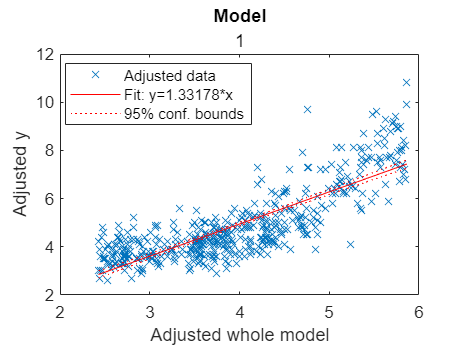

plot(model)
title("Model",n)

model_summaries(n,:) = {n, "mass,fuel",model.Rsquared.Ordinary, model.MSE, model.ModelCriterion.AIC};

Shows quite a bit of improvement from using just mass

### **Model 2)** Mass, engine disp, and fuel type

n = 2

n = 2

x = [mass,disp, fuel];
model = fitlm(x,y)

model = Linear regression model:
    y ~ 1 + x1 + x2 + x3

Estimated Coefficients:
                   Estimate         SE         tStat       pValue  
                   _________    __________    _______    __________

    (Intercept)      -1.4409       0.20175    -7.1419    3.2995e-12
    x1             0.0021006    7.9551e-05     26.405      1.32e-96
    x2               0.34271      0.040012     8.5651     1.369e-16
    x3                1.3975       0.07407     18.868    2.9677e-60


Number of observations: 500, Error degrees of freedom: 496
Root Mean Squared Error: 0.816
R-squared: 0.717,  Adjusted R-Squared: 0.715
F-statistic vs. constant model: 418, p-value = 2.34e-135

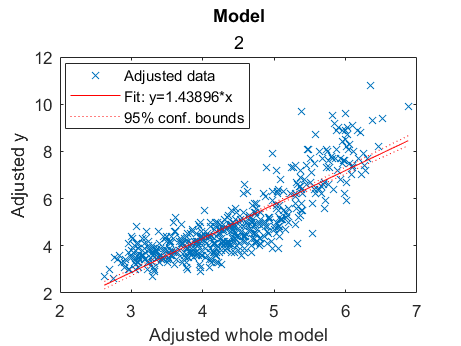

plot(model)
title("Model",n)

model_summaries(n,:) = {n, "mass,disp,fuel",model.Rsquared.Ordinary, model.MSE, model.ModelCriterion.AIC};

Noticeable improvement over Model 1

### **Model 3)** Mass, engine disp, fuel, and time100

n = 3

n = 3

x = [mass, disp, fuel,time];
model = fitlm(x,y)

model = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4

Estimated Coefficients:
                   Estimate         SE         tStat       pValue  
                   _________    __________    _______    __________

    (Intercept)      0.88901       0.73379     1.2115       0.22627
    x1             0.0020982    7.8773e-05     26.636    1.2176e-97
    x2               0.12279      0.077532     1.5838       0.11389
    x3                1.4029       0.07336     19.123    1.8965e-61
    x4              -0.17085      0.051775    -3.2998     0.0010373


Number of observations: 500, Error degrees of freedom: 495
Root Mean Squared Error: 0.808
R-squared: 0.723,  Adjusted R-Squared: 0.72
F-statistic vs. constant model: 323, p-value = 2.4e-136

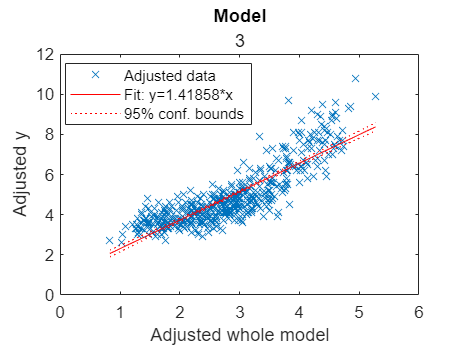

plot(model)
title("Model",n)

model_summaries(n,:) = {n, "mass,disp,fuel,time",model.Rsquared.Ordinary, model.MSE, model.ModelCriterion.AIC};

Again we observe an improvement in all metrics, although somewhat slightly

### **Model 4)** Mass, engine disp, fuel, and mass*fuel

n = 4

n = 4

mass_fuel_inter = mass.*fuel;
x = [mass, disp, fuel ,mass_fuel_inter];
model = fitlm(x,y)

model = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4

Estimated Coefficients:
                    Estimate         SE         tStat       pValue  
                   __________    __________    _______    __________

    (Intercept)        3.5894       0.35489     10.114    5.5041e-22
    x1             -0.0011346    0.00021249    -5.3398    1.4203e-07
    x2                0.32393      0.032549     9.9521     2.156e-21
    x3                -1.8438       0.21154    -8.7161    4.3625e-17
    x4               0.002081    0.00013019     15.984    1.1333e-46


Number of observations: 500, Error degrees of freedom: 495
Root Mean Squared Error: 0.664
R-squared: 0.813,  Adjusted R-Squared: 0.812
F-statistic vs. constant model: 538, p-value = 1.09e-178

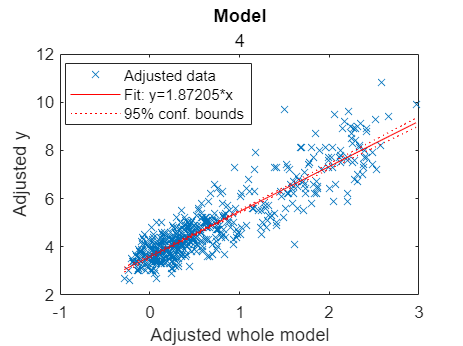

plot(model)
title("Model",n)

model_summaries(n,:) = {n, "mass,disp,fuel,mass*fuel",model.Rsquared.Ordinary, model.MSE, model.ModelCriterion.AIC};

We can observe a very significant improvement in all metrics now. I'll now test it with the time parameter to see if that adds improvement

### **Model 5)** Mass, engine disp, fuel,time, and mass*fuel

n = 5

n = 5

mass_fuel_inter = mass.*fuel;
x = [mass, disp, fuel,time, mass_fuel_inter];
model = fitlm(x,y)

model = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5

Estimated Coefficients:
                   Estimate         SE         tStat       pValue  
                   _________    __________    _______    __________

    (Intercept)       6.3406       0.67603     9.3791    2.4031e-19
    x1             -0.001174    0.00020818    -5.6391    2.8791e-08
    x2              0.069416        0.0624     1.1124       0.26649
    x3               -1.8743       0.20719    -9.0462    3.3918e-18
    x4              -0.19757      0.041646    -4.7439    2.7477e-06
    x5             0.0021045    0.00012755       16.5    4.9118e-49


Number of observations: 500, Error degrees of freedom: 494
Root Mean Squared Error: 0.65
R-squared: 0.821,  Adjusted R-Squ

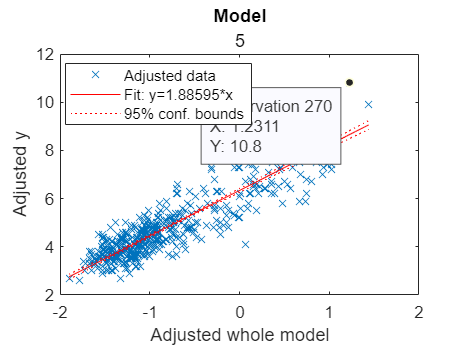

plot(model)
title("Model",n)

model_summaries(n,:) = {n, "mass,disp,fuel,time,mass*fuel",model.Rsquared.Ordinary, model.MSE, model.ModelCriterion.AIC};

We see a slight improvement now as well. Let's try adding some more interaction terms to this model

### **Model 6)** Mass, engine disp, fuel, time, mass*fuel, fuel*disp

n = 6

n = 6

mass_fuel_inter = mass.*fuel;
fuel_disp_inter = fuel.*disp;
x = [mass, disp, fuel,time, mass_fuel_inter,fuel_disp_inter];
model = fitlm(x,y)

model = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6

Estimated Coefficients:
                    Estimate         SE         tStat       pValue  
                   __________    __________    _______    __________

    (Intercept)        6.4611       0.70992     9.1012    2.2145e-18
    x1             -0.0011727    0.00020834    -5.6288    3.0487e-08
    x2               0.019801       0.10838    0.18271        0.8551
    x3                -1.9747       0.27403    -7.2059    2.1753e-12
    x4               -0.19546      0.041845    -4.6709    3.8723e-06
    x5              0.0021028    0.00012767      16.47    7.0331e-49
    x6               0.036029      0.064323    0.56013       0.57565


Number of observations:

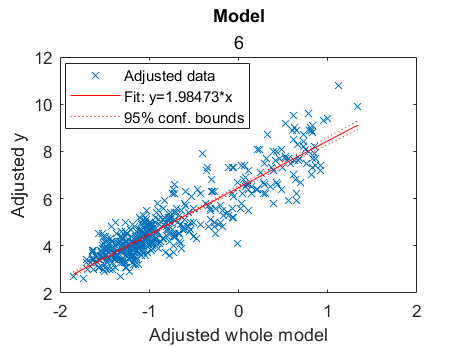

plot(model)
title("Model",n)

model_summaries(n,:) = {n, "mass,disp,fuel,time,mass*fuel,fuel*disp",model.Rsquared.Ordinary, model.MSE, model.ModelCriterion.AIC};

Accuracy is barely changed from model5, and there is a small uptick in AIC. Likely too complicated of a model here.

### **Model 7)** Mass, engine disp, fuel, time, mass*fuel, disp/time

n = 7

n = 7

mass_fuel_inter = mass.*fuel;
disp_time_inter = disp./time;
x = [mass, disp, fuel,time, mass_fuel_inter,disp_time_inter];
model = fitlm(x,y)

model = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6

Estimated Coefficients:
                    Estimate         SE          tStat        pValue  
                   __________    __________    _________    __________

    (Intercept)        6.2465       0.69519       8.9854    5.4927e-18
    x1             -0.0011651    0.00020887      -5.5781    4.0158e-08
    x2              -0.002423       0.13743    -0.017631       0.98594
    x3                -1.8677       0.20763      -8.9956    5.0748e-18
    x4               -0.18584      0.046215      -4.0212    6.6965e-05
    x5              0.0021002    0.00012784       16.428    1.0938e-48
    x6                0.55476       0.94538      0.58681        0.5576


Numbe

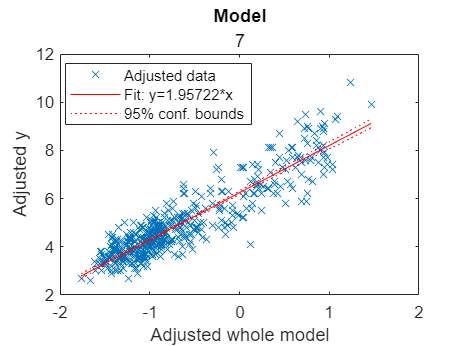

plot(model)
title("Model",n)

model_summaries(n,:) = {n, "mass,disp,fuel,time,mass*fuel,disp/time",model.Rsquared.Ordinary, model.MSE, model.ModelCriterion.AIC};

Pretty much the same metrics as model 6. 

It seems making the model more complicated doesnt help much so let's try cutting down.

### **Model 8)** Mass, engine disp, fuel, mass*fuel, disp/time

n = 8

n = 8

mass_fuel_inter = mass.*fuel;
disp_time_inter = disp./time;
x = [mass, disp, fuel, mass_fuel_inter,disp_time_inter];
model = fitlm(x,y)

model = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5

Estimated Coefficients:
                    Estimate         SE         tStat        pValue  
                   __________    __________    ________    __________

    (Intercept)        3.8638       0.36911      10.468    2.6985e-23
    x1             -0.0011087    0.00021157     -5.2402    2.3799e-07
    x2              -0.020565       0.13945    -0.14748       0.88281
    x3                 -1.825       0.21052     -8.6692    6.2756e-17
    x4              0.0020696    0.00012956      15.974    1.3066e-46
    x5                 2.1982       0.86547      2.5399      0.011395


Number of observations: 500, Error degrees of freedom: 494
Root Mean Squared Error: 0.66
R-squared: 0.815,

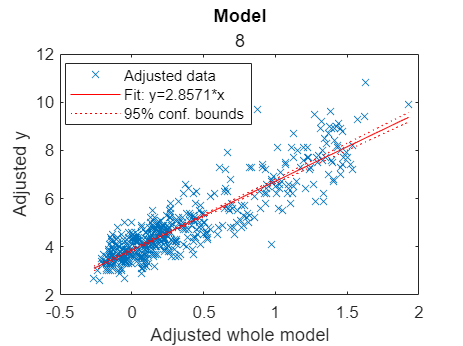

plot(model)
title("Model",n)

model_summaries(n,:) = {n, "mass,disp,fuel,mass*fuel,disp/time",model.Rsquared.Ordinary, model.MSE, model.ModelCriterion.AIC};

Comparing with model#5, it doesn't seem disp/time is a better substitute then time, as all metrics show degradation.

### **Model 9)** Engine disp, time, mass*fuel 

n = 9

n = 9

mass_fuel_inter = mass.*fuel;
x = [disp, time, mass_fuel_inter];
model = fitlm(x,y)

model = Linear regression model:
    y ~ 1 + x1 + x2 + x3

Estimated Coefficients:
                   Estimate         SE         tStat       pValue   
                   _________    __________    _______    ___________

    (Intercept)       3.8027       0.64219     5.9215     5.9652e-09
    x1               0.10715       0.06906     1.5515        0.12141
    x2              -0.19254      0.046136    -4.1733     3.5458e-05
    x3             0.0011499    2.8059e-05     40.982    2.3559e-161


Number of observations: 500, Error degrees of freedom: 496
Root Mean Squared Error: 0.72
R-squared: 0.779,  Adjusted R-Squared: 0.778
F-statistic vs. constant model: 584, p-value = 2.76e-162

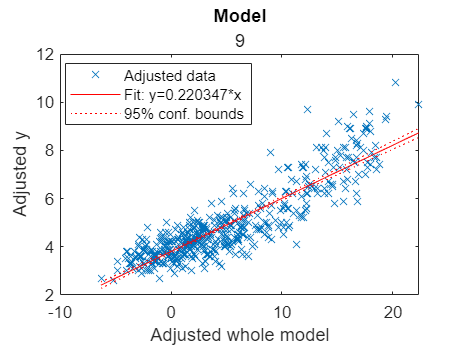

plot(model)
title("Model",n)

model_summaries(n,:) = {n, "disp,time,mass*fuel",model.Rsquared.Ordinary, model.MSE, model.ModelCriterion.AIC};

Comparing with model#5, it seems that mass*fuel term is not a substitute for mass and fuel separately. Accuracies decrease and AIC increases

### **Model 10)** Mass,fuel, disp,time, + 5 interaction terms generated by matlab

Try something really complex

n = 10

n = 10

x = [mass, fuel, disp,time];
model = fitlm(x,y,"interactions")

model = Linear regression model:
    y ~ 1 + x1*x2 + x1*x3 + x1*x4 + x2*x3 + x2*x4 + x3*x4

Estimated Coefficients:
                    Estimate          SE         tStat        pValue  
                   ___________    __________    ________    __________

    (Intercept)         2.3613         2.542      0.9289        0.3534
    x1              0.00012595     0.0013196    0.095443         0.924
    x2                -0.77876        1.2058    -0.64583       0.51869
    x3                 0.39814       0.30263      1.3156       0.18893
    x4                 0.15624        0.1866     0.83733       0.40282
    x1:x2            0.0021236    0.00012848      16.529    4.4529e-49
    x1:x3          -3.5794e-05    0.00013697    -0.26132    

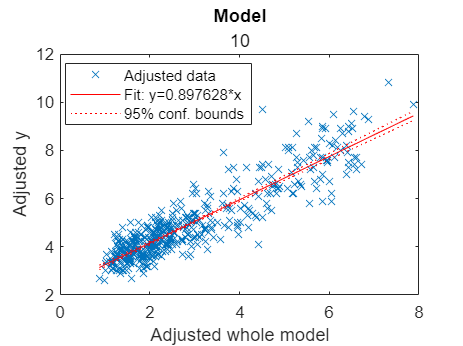

plot(model)
title("Model",n)

model_summaries(n,:) = {n, "mass,fuel,diso,time + 6 interactions",model.Rsquared.Ordinary, model.MSE, model.ModelCriterion.AIC};

This is the most accurate model we got, but is really complex, and its AIC is higher than 5

**Inspect Model Summaries**

model_summaries

model_summaries = 10×5 table
    Model#                      Terms                        R^2        MSE       AIC  
    ______    _________________________________________    _______    _______    ______

       1      "mass,fuel"                                   0.6747    0.76373    1287.2
       2      "mass,disp,fuel"                             0.71661    0.66667    1220.2
       3      "mass,disp,fuel,time"                        0.72271    0.65364    1211.3
       4      "mass,disp,fuel,mass*fuel"                   0.81308    0.44061    1014.1
       5      "mass,disp,fuel,time,mass*fuel"              0.82123    0.42226    993.84
       6      "mass,disp,fuel,time,mass*fuel,fuel*disp"    0.82134    0.42285    995.52
       7      "mass,disp,fuel,time,mass*fuel,disp/time"    0.82135    0.42282    995.49
       8

**Decide on best model**

.Model 5 outperforms 1,2,3,4, in accuracy and has higher AIC, meaning its not overly complex.

Models 6 and 7 pretty much have the same accuracy in terms of R2 and MSE as Model5, but have an added interaction term that drives up the AIC. So they are not preferred over #5

Model 8 is not as accurate as 5, and is no less complex, as it substitutes time with an interaction term involving time.

Model 9 is simpler yet noticably less accurate then #5, and its AIC shows the simplification does not compensate.

Model 10 is the most accurate of them all. It has slightly higher R2 and lower MSE than #5, but its AIC is higher, meaning its overcomplicated given its accuracy. It will likely overfit the data

**So I will go with Model#5: Mass,Fuel,Time,Disp,Mass*Fuel**

## **Q3) A)Calculate residuals**

**Redo model**

mass_fuel_inter = mass.*fuel

mass_fuel_inter =          997
        2050
        1265
        1578
        2343
        1306
        1934
        2051
         960
         934


x = [mass, disp, fuel,time, mass_fuel_inter];
model = fitlm(x,y)

model = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5

Estimated Coefficients:
                   Estimate         SE         tStat       pValue  
                   _________    __________    _______    __________

    (Intercept)       6.3406       0.67603     9.3791    2.4031e-19
    x1             -0.001174    0.00020818    -5.6391    2.8791e-08
    x2              0.069416        0.0624     1.1124       0.26649
    x3               -1.8743       0.20719    -9.0462    3.3918e-18
    x4              -0.19757      0.041646    -4.7439    2.7477e-06
    x5             0.0021045    0.00012755       16.5    4.9118e-49


Number of observations: 500, Error degrees of freedom: 494
Root Mean Squared Error: 0.65
R-squared: 0.821,  Adjusted R-Squ

**Plot residuals vs fitted values**

Here I am checking if there is a noticable pattern between the errors(residuals) and the fitted data. Perhaps the model performs poorly on a given range of outputs.

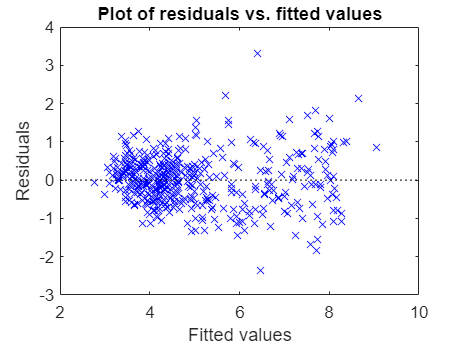

plotResiduals(model,"fitted")

Upon inspection, it seems that the model is performing best on fuel consumption values between 3 and 5. For higher fuel consumption figures the residuals seem, on average, to be much larger, and are also dispersed more widely. This suggests the model is more accurate in predicting lower fuel consumptions than higher ones.

**QQ Plot of Residuals**

Here I am trying to check if the errors are indeed normally distributed. I will take the raw residuals

residuals = table2array(model.Residuals(:,1))

residuals =    -0.3865
    0.3052
    0.6439
    0.0409
    0.4668
   -0.3268
    0.6944
   -0.6401
   -0.3813
    0.2129


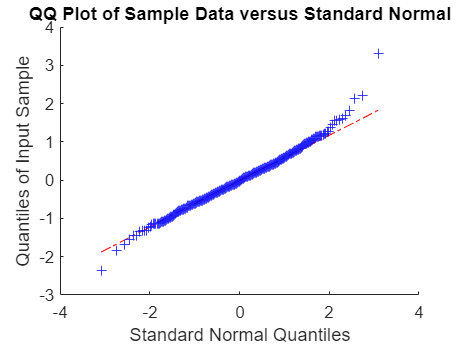

qqplot(residuals)

The QQ plot shows that the empirical quantiles approximate the true quantiles quite well up to the last segment of the data, i.e. the higher fuel consumption figures. So the residuals seem to be normally distributed overall, but again this QQplot confirms our previous suspicion about inaccuracies in predicting high fuel consumptions. There also seems to be deviations from a normal distribution while predicting low fuel consumptions

**Theoretical and Empriical CDF**

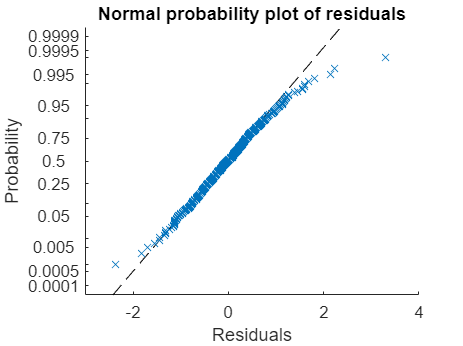

plotResiduals(model,"probability")

Plots of theoretical and empirical cdf (blue dots) serve to corraborate our conclusions from the qqplot.

### **B)Interpret the regression coefficients and suggest improvements**

"X1= mass, X2= disp X3= fuel X4=time X5= mass*fuel"

ans = "X1= mass, X2= disp X3= fuel X4=time X5= mass*fuel"

model

model = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5

Estimated Coefficients:
                   Estimate         SE         tStat       pValue  
                   _________    __________    _______    __________

    (Intercept)       6.3406       0.67603     9.3791    2.4031e-19
    x1             -0.001174    0.00020818    -5.6391    2.8791e-08
    x2              0.069416        0.0624     1.1124       0.26649
    x3               -1.8743       0.20719    -9.0462    3.3918e-18
    x4              -0.19757      0.041646    -4.7439    2.7477e-06
    x5             0.0021045    0.00012755       16.5    4.9118e-49


Number of observations: 500, Error degrees of freedom: 494
Root Mean Squared Error: 0.65
R-squared: 0.821,  Adjusted R-Squ

**Intercept**

The intercept, 6.34, gives us the mean of the output when all the predictory variables we use are zero. This is sort of meaningless now here as a car with zero valued parameters couldn't really exist. Intuitively we could expect this intercept to be zero. We could force the intercept to be zero but this could make the model more inaccurate

model_int = fitlm(x,y,"Intercept",false)

model_int = Linear regression model:
    y ~ x1 + x2 + x3 + x4 + x5

Estimated Coefficients:
           Estimate          SE         tStat       pValue  
          ___________    __________    _______    __________

    x1    -0.00018544    0.00019466    -0.9526       0.34126
    x2        0.54953      0.038693     14.202    1.2073e-38
    x3       -0.90473       0.19469    -4.6469    4.3258e-06
    x4        0.13751      0.023207     5.9255    5.8378e-09
    x5      0.0015198    0.00012066     12.596    9.4195e-32


Number of observations: 500, Error degrees of freedom: 495
Root Mean Squared Error: 0.705

model_int

model_int = Linear regression model:
    y ~ x1 + x2 + x3 + x4 + x5

Estimated Coefficients:
           Estimate          SE         tStat       pValue  
          ___________    __________    _______    __________

    x1    -0.00018544    0.00019466    -0.9526       0.34126
    x2        0.54953      0.038693     14.202    1.2073e-38
    x3       -0.90473       0.19469    -4.6469    4.3258e-06
    x4        0.13751      0.023207     5.9255    5.8378e-09
    x5      0.0015198    0.00012066     12.596    9.4195e-32


Number of observations: 500, Error degrees of freedom: 495
Root Mean Squared Error: 0.705

model_int.ModelCriterion.AIC

ans = 1.0738e+03

model_int.Rsquared

ans = struct with fields:
    Ordinary: 0.7894
    Adjusted: 0.7877


This is less accurate than our model and there is realistically a lower limit on car parameters (i.e. mass and engine size can't just e zero) so we can ignore this.

**Betas**

All the betas except beta/x2 have p values much smaller than 0.05, meaning they are very unlikely to be zero. X2's p value is 0.26649, so it may not be statistically significant to consider it as being yective. 

All the other terms seem to be very signficiant, so I will try running the model without the disp term present.

mass_fuel_inter = mass.*fuel;
x_new = [mass, fuel,time, mass_fuel_inter];
model_new = fitlm(x_new,y)

model_new = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4

Estimated Coefficients:
                    Estimate         SE         tStat       pValue  
                   __________    __________    _______    __________

    (Intercept)        6.9575        0.3867     17.992    4.6632e-56
    x1             -0.0011852    0.00020799    -5.6984    2.0783e-08
    x2                 -1.888       0.20687    -9.1262    1.7963e-18
    x3                -0.2374      0.021271     -11.16    5.9471e-26
    x4              0.0021118    0.00012741     16.576    2.0899e-49


Number of observations: 500, Error degrees of freedom: 495
Root Mean Squared Error: 0.65
R-squared: 0.821,  Adjusted R-Squared: 0.819
F-statistic vs. constant model: 567, p-value = 3.33e-183

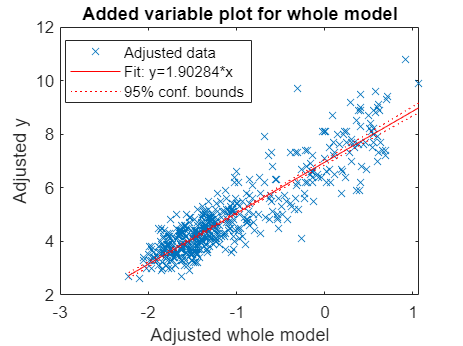

plot(model_new)

model_new.ModelCriterion.AIC

ans = 993.0877

model_new.Rsquared

ans = struct with fields:
    Ordinary: 0.8208
    Adjusted: 0.8193


model_new.MSE

ans = 0.4225

This yields a model that is slightly less accurate than model#5, but also has a sligthly lower AIC. 

I will go with this model given that it is less complex then our previous model, and the high p value for x2 means I can not reject the null hypothesis that the yect of disp in this model is null with statistical confidence

x = x_new

x = 	1.0e+03 *

    0.9970    0.0010    0.0086    0.9970
    2.0500    0.0010    0.0106    2.0500
    1.2650    0.0010    0.0097    1.2650
    1.5780    0.0010    0.0095    1.5780
    2.3430    0.0010    0.0118    2.3430
    1.3060    0.0010    0.0095    1.3060
    1.9340    0.0010    0.0104    1.9340
    2.0510    0.0010    0.0102    2.0510
    0.9600    0.0010    0.0126    0.9600
    0.9340    0.0010    0.0110    0.9340


model = model_new

model = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4

Estimated Coefficients:
                    Estimate         SE         tStat       pValue  
                   __________    __________    _______    __________

    (Intercept)        6.9575        0.3867     17.992    4.6632e-56
    x1             -0.0011852    0.00020799    -5.6984    2.0783e-08
    x2                 -1.888       0.20687    -9.1262    1.7963e-18
    x3                -0.2374      0.021271     -11.16    5.9471e-26
    x4              0.0021118    0.00012741     16.576    2.0899e-49


Number of observations: 500, Error degrees of freedom: 495
Root Mean Squared Error: 0.65
R-squared: 0.821,  Adjusted R-Squared: 0.819
F-statistic vs. constant model: 567, p-value = 3.33e-183

Now we can say with confidence, thanks to the low pValues, that the regression parameters contribute meaningfully to our predictions.

**Interpretation of coyicients**

From our previous analysis of scatter plots and model 3 in particular we would expect coyicients x1 and x2 to be positive, so that cars with more mass, and cars burning petrol rather than diesel, consume more fuel. However the coyicient x4 for our interaction term, captures this relationship. It is, as expected, positive. X1 and X2 are counterintuitively negative. The positive x4 and negative x1 x2 are yective in fine tuning the model. The different models demonstrated that mass*fuel is a useful additional info and is a very good predictor. This might be because the yect of running a more economical diesel engine is more pronounced when the car is even heavier, and vice versa.

X3 is predictably negative, so that cars with higher acceleration times, i.e. slower accelerations, consume less fuel.

# **Q4) Clustering**

**Perform cluster analysis to identify two distinct groups of cars**

% Perform K means
[idx,C] = kmeans(x,2);
% Use Logical indexing to separate data by category
x_idx = [idx,x]

x_idx = 	1.0e+03 *

    0.0010    0.9970    0.0010    0.0086    0.9970
    0.0010    2.0500    0.0010    0.0106    2.0500
    0.0010    1.2650    0.0010    0.0097    1.2650
    0.0010    1.5780    0.0010    0.0095    1.5780
    0.0010    2.3430    0.0010    0.0118    2.3430
    0.0010    1.3060    0.0010    0.0095    1.3060
    0.0010    1.9340    0.0010    0.0104    1.9340
    0.0010    2.0510    0.0010    0.0102    2.0510
    0.0010    0.9600    0.0010    0.0126    0.9600
    0.0010    0.9340    0.0010    0.0110    0.9340


cat_1 = x_idx(:,1) < 2 

cat_1 = 500×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


cat_2 = x_idx(:,1) > 1

cat_2 = 500×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


x_1 = x(cat_1,:);
x_2 = x(cat_2,:);

% Further indexing two separate each category by fuel type (will be useful)
% in below plot) - 1 is diesel, 2 is petrol
% Create logical indices
idx_1d =x_1(:,2) < 2

idx_1d = 362×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


idx_1p = x_1(:,2) > 1

idx_1p = 362×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


idx_2d = x_2(:,2) < 2 

idx_2d = 138×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


idx_2p =x_2(:,2) > 1

idx_2p = 138×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


% Separate datasets
x_1_diesel = x_1(idx_1d,:)

x_1_diesel = 	1.0e+03 *

    0.9970    0.0010    0.0086    0.9970
    2.0500    0.0010    0.0106    2.0500
    1.2650    0.0010    0.0097    1.2650
    1.5780    0.0010    0.0095    1.5780
    2.3430    0.0010    0.0118    2.3430
    1.3060    0.0010    0.0095    1.3060
    1.9340    0.0010    0.0104    1.9340
    2.0510    0.0010    0.0102    2.0510
    0.9600    0.0010    0.0126    0.9600
    0.9340    0.0010    0.0110    0.9340


x_1_petrol = x_1(idx_1p,:)

x_1_petrol = 	1.0e+03 *

    1.2070    0.0020    0.0098    2.4140
    1.3190    0.0020    0.0092    2.6380
    1.2770    0.0020    0.0103    2.5540
    1.2760    0.0020    0.0104    2.5520
    0.9830    0.0020    0.0115    1.9660
    1.1830    0.0020    0.0103    2.3660
    1.3080    0.0020    0.0103    2.6160
    0.9950    0.0020    0.0099    1.9900
    1.1480    0.0020    0.0092    2.2960
    0.9700    0.0020    0.0086    1.9400


x_2_diesel = x_2(idx_2d,:) % No diesel cars in category 2


x_2_diesel =

  0×4 empty double matrix



x_2_petrol = x_2(idx_2p,:)

x_2_petrol = 	1.0e+03 *

    2.3770    0.0020    0.0095    4.7540
    1.5880    0.0020    0.0089    3.1760
    2.3540    0.0020    0.0085    4.7080
    1.7410    0.0020    0.0089    3.4820
    1.6720    0.0020    0.0105    3.3440
    2.1940    0.0020    0.0089    4.3880
    2.3970    0.0020    0.0136    4.7940
    2.2510    0.0020    0.0098    4.5020
    1.6940    0.0020    0.0101    3.3880
    2.1870    0.0020    0.0089    4.3740


**Plot the different categories on cars in a mass v fuel consumption plot, with fuel types indicated**

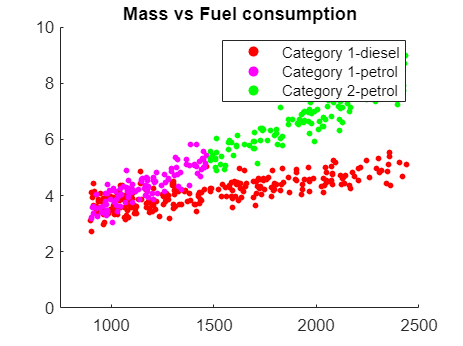

% Get the fuel consumptions for each category
y1_diesel = model.predict(x_1_diesel);
y1_petrol = model.predict(x_1_petrol);
y2_diesel = model.predict(x_2_diesel);
y2_petrol = model.predict(x_2_petrol);
% Plot
scatter(x_1_diesel(:,1), y1_diesel, 12, "red","filled")
hold on
scatter(x_1_petrol(:,1), y1_petrol, 12, "magenta","filled")
scatter(x_2_petrol(:,1), y2_petrol, 12, "green","filled")

legend("Category 1-diesel","Category 1-petrol", "Category 2-petrol")
title("Mass vs Fuel consumption")
axis([750,2500,0,10])
hold off

The clusters observed in the above plots point to an interesting observation. Notice that all diesel cars are in cluster 1, along with petrol cars with low fuel consumptions, up to about 5l/100km. 

This suggests that petrol and diesel cars should have separate regression models, as their best fit lines clearly seem to be different.

# **Q5) Predictions on test set**

**Prepare data**

test_data

test_data = 500×6 table
    l100    mass    time100    displacement       type        colour  
    ____    ____    _______    ____________    __________    _________

    3.4     2218     11.9            2         {'diesel'}    {'white'}
    3.8     1977     10.8          2.1         {'diesel'}    {'other'}
    4.6      983     10.8          2.1         {'diesel'}    {'other'}
      4     2310      9.9            2         {'diesel'}    {'white'}
    3.4     1233       12          1.9         {'diesel'}    {'other'}
    4.1     1004     10.1          3.1         {'diesel'}    {'other'}
    3.7      921     10.6          2.1         {'diesel'}    {'white'}
    3.7     1678      9.2          3.8         {'diesel'}    {'other'}
    3.1     1377     11.3          2.2         {'diesel'}    

y_test = table2array(test_data(:,1));
% Get all x terms
x1 = table2array(test_data(:,2)); % Mass
x2 = table2array(test_data(:,5)); % Fuel
c = categorical({'petrol','diesel'})

c = 1×2 categorical array
     petrol      diesel 


x2 = grp2idx(x2); % Encoded fuel
x3 = table2array(test_data(:,3)); % Time
x4 = x1.*x2 %mass *fuel

x4 =         2218
        1977
         983
        2310
        1233
        1004
         921
        1678
        1377
        2083


% Overall x matrix
x_test = [x1,x2,x3,x4]

x_test = 	1.0e+03 *

    2.2180    0.0010    0.0119    2.2180
    1.9770    0.0010    0.0108    1.9770
    0.9830    0.0010    0.0108    0.9830
    2.3100    0.0010    0.0099    2.3100
    1.2330    0.0010    0.0120    1.2330
    1.0040    0.0010    0.0101    1.0040
    0.9210    0.0010    0.0106    0.9210
    1.6780    0.0010    0.0092    1.6780
    1.3770    0.0010    0.0113    1.3770
    2.0830    0.0010    0.0120    2.0830


% Summary stats for output
y_mean = mean(y_test)

y_mean = 4.7372

y_median = median(y_test)

y_median = 4.4000

y_std = std(y_test)

y_std = 1.3232

y_iqr = iqr(y_test)

y_iqr = 1.5000

**Fit model and plot**

model

model = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4

Estimated Coefficients:
                    Estimate         SE         tStat       pValue  
                   __________    __________    _______    __________

    (Intercept)        6.9575        0.3867     17.992    4.6632e-56
    x1             -0.0011852    0.00020799    -5.6984    2.0783e-08
    x2                 -1.888       0.20687    -9.1262    1.7963e-18
    x3                -0.2374      0.021271     -11.16    5.9471e-26
    x4              0.0021118    0.00012741     16.576    2.0899e-49


Number of observations: 500, Error degrees of freedom: 495
Root Mean Squared Error: 0.65
R-squared: 0.821,  Adjusted R-Squared: 0.819
F-statistic vs. constant model: 567, p-value = 3.33e-183

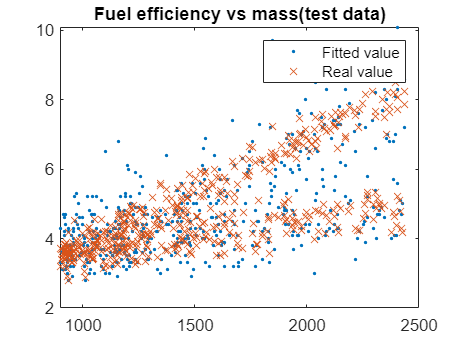

y_pred = predict(model,x_test);
plot(x1,y_test,".",x1,y_pred,"x")
legend("Fitted value", "Real value")
title("Fuel efficiency vs mass(test data)")

For comparison we can plot this identical plot for the training data

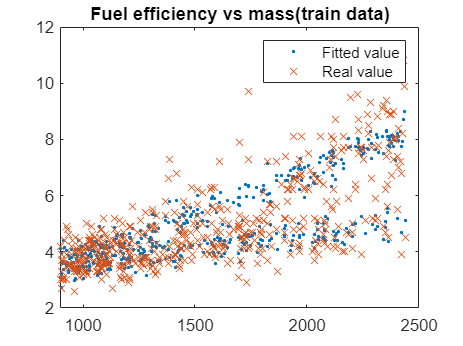

y_pred_test = predict(model,x);
plot(mass,y_pred_test,".",mass,y,"x")
legend("Fitted value", "Real value")
title("Fuel efficiency vs mass(train data)")

The model seems to perform similarly based on the plots

**Calculate metrics**

mse_test = mean((y_test - y_pred).^2)

mse_test = 0.4103

mse_train = model.MSE

mse_train = 0.4225

The MSE is slightly lower for our test data predictions. This is a good sign that the model is not overfitting. 

The model seems simple enough and not in need of regularization.